# This exercise is to forecast volatility via different methods, campared with actual volatilities measured by high-frequency realised volatility

The difference with "exercise_VolForecastRV20220521.mlx" is to check robustness of the length of rolling windows. This is to extend the window from 252 to 500.

clc,clear
addpath("data_Files/")
addpath("m_Files_ClusterPartition/")
addpath("m_Files_GARCHfamily/")
addpath("m_Files_Color/colormap/");

load("dax_rv.mat")
load("ftse_rv.mat")
load("nikkie_rv.mat")
load("sp_rv.mat")
dax=readtable("DAX daily.xlsx");
dax(:,3:end)=[];dax.Properties.VariableNames=["Date","Price"]
ftse=readtable("FTSE daily.xlsx");
ftse(:,3:end)=[];ftse.Properties.VariableNames=["Date","Price"]
nikkie=readtable("NIKKIE daily.xlsx");
nikkie(:,3:end)=[];nikkie.Properties.VariableNames=["Date","Price"]
sp=readtable("S&P500 daily.xlsx");
sp(:,3:end)=[];sp.Properties.VariableNames=["Date","Price"]

## SP500

Timeline=sp.Date;
Time_outsample=sp_rv_table.date;
logret=[0;price2ret(sp.Price)];
rv=sp_rv_table.rv;
Index='sp';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-500:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset');
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],10,[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");
%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);
[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);
[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

## Figure of volatility persistence

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_robust_',Index,'_20220522'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");

## DAX30

Timeline=dax.Date;
Time_outsample=dax_rv_table.date;
logret=[0;price2ret(dax.Price)];
rv=dax_rv_table.rv;
Index='dax';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-500:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

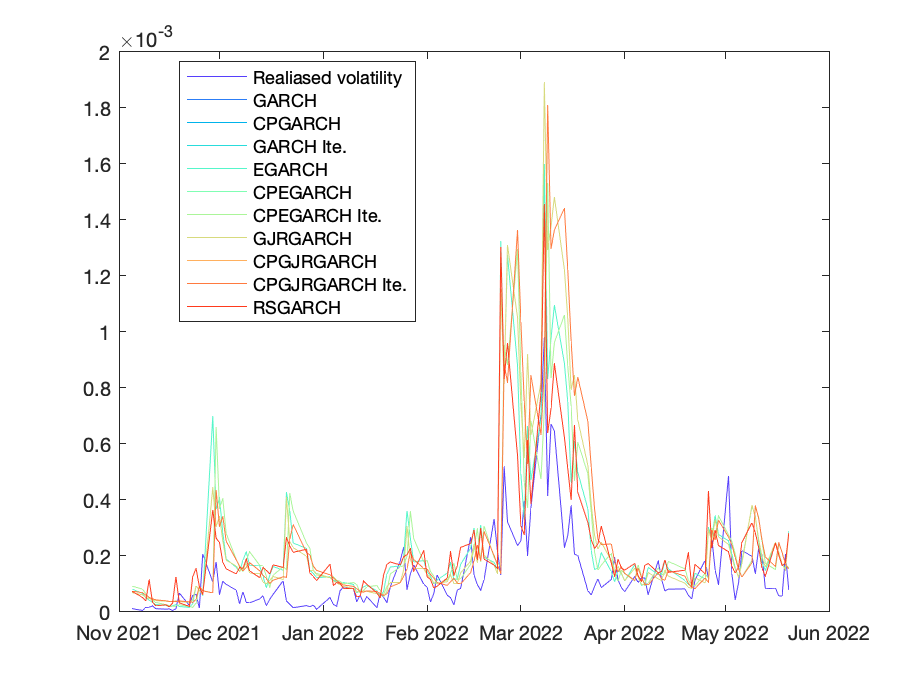

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              0.00015984    0.00027703
    CPGARCH            0.00015575    0.00028201
    GARCH Ite.         0.00015575    0.00028201
    EGARCH             0.00013728    0.00022418
    CPEGARCH           0.00013926    0.00022661
    CPEGARCH Ite.      0.00013926    0.00022661
    GJRGARCH           0.00015984    0.00027704
    CPGJRGARCH         0.00015575    0.00028201
    CPGJRGARCH Ite.    0.00015575    0.00028201
    RSGARCH            0.00011814     0.0001803


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);
[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);
[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound      R2   
                       _________    ___________    _______

    GARCH               0.29187       0.38873      0.58853
    CPGARCH             0.25114       0.36588      0.45587
    GARCH Ite.          0.25114       0.36588      0.45587
    EGARCH              0.33538       0.46442      0.52678
    CPEGARCH            0.29855        0.4482      0.41905
    CPEGARCH Ite.       0.29855        0.4482      0.41905
    GJRGARCH            0.29186       0.38872      0.58856
    CPGJRGARCH          0.25114       0.36588      0.45588
    CPGJRGARCH Ite.     0.25114       0.36588      0.45588
    RSGARCH             0.41588       0.56881      0.54569


## Figure of volatility persistence

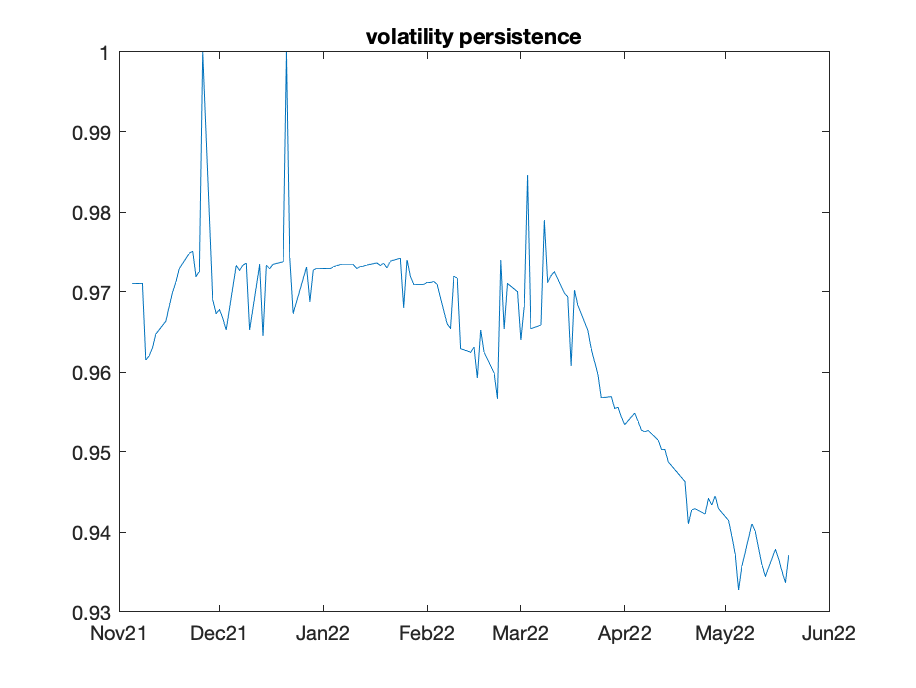

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_robust_',Index,'_20220522'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");

## FTSE 100

Timeline=ftse.Date;
Time_outsample=ftse_rv_table.date;
logret=[0;price2ret(ftse.Price)];
rv=ftse_rv_table.rv;
Index='ftse';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-500:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

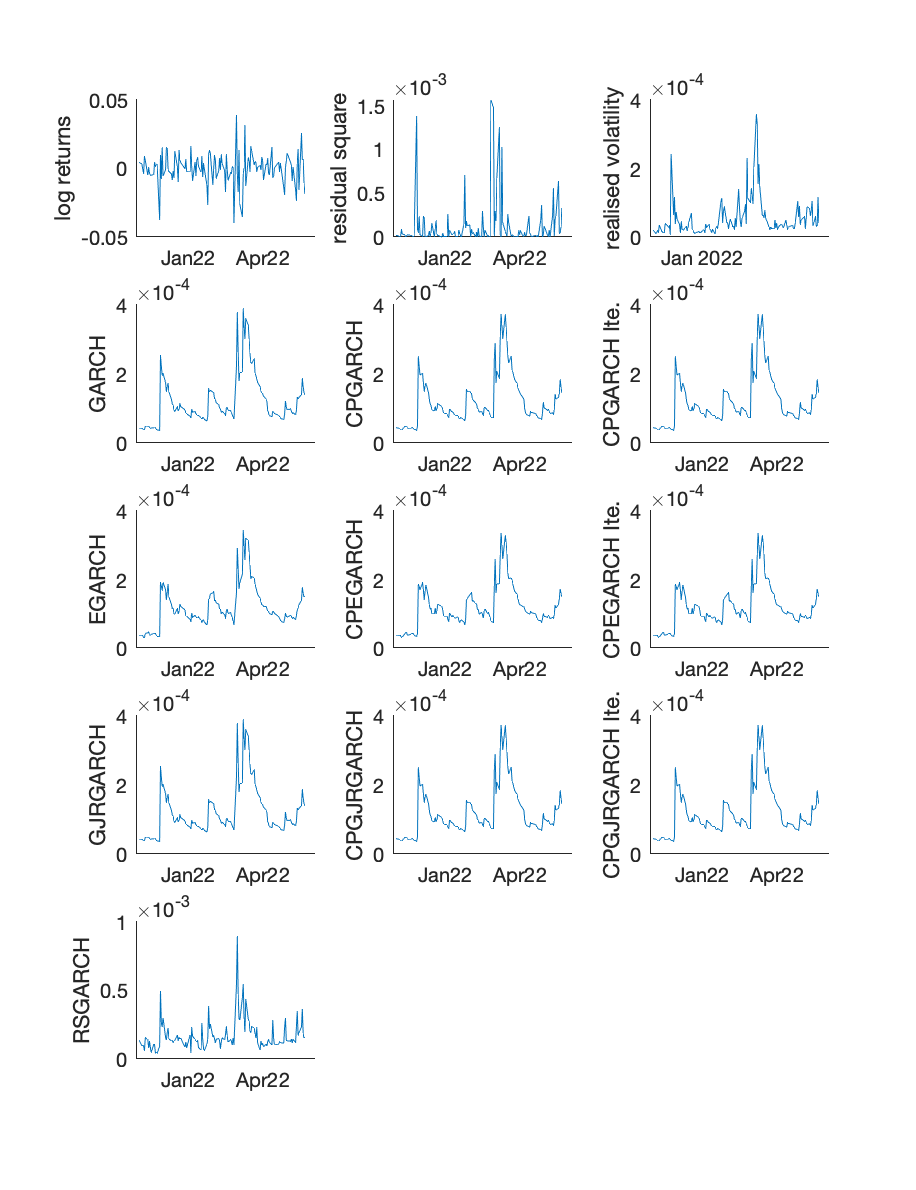

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

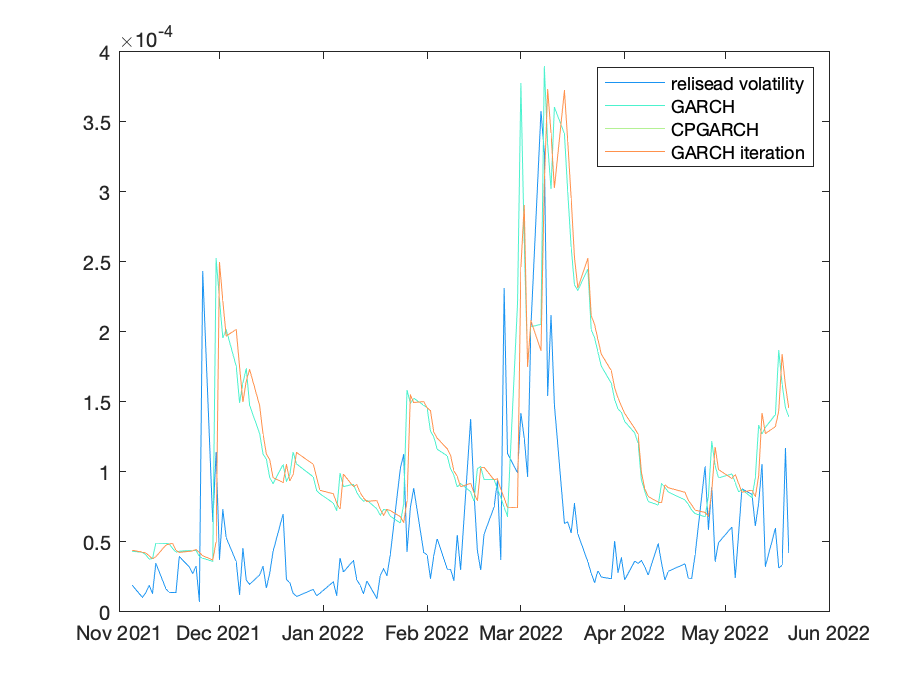

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

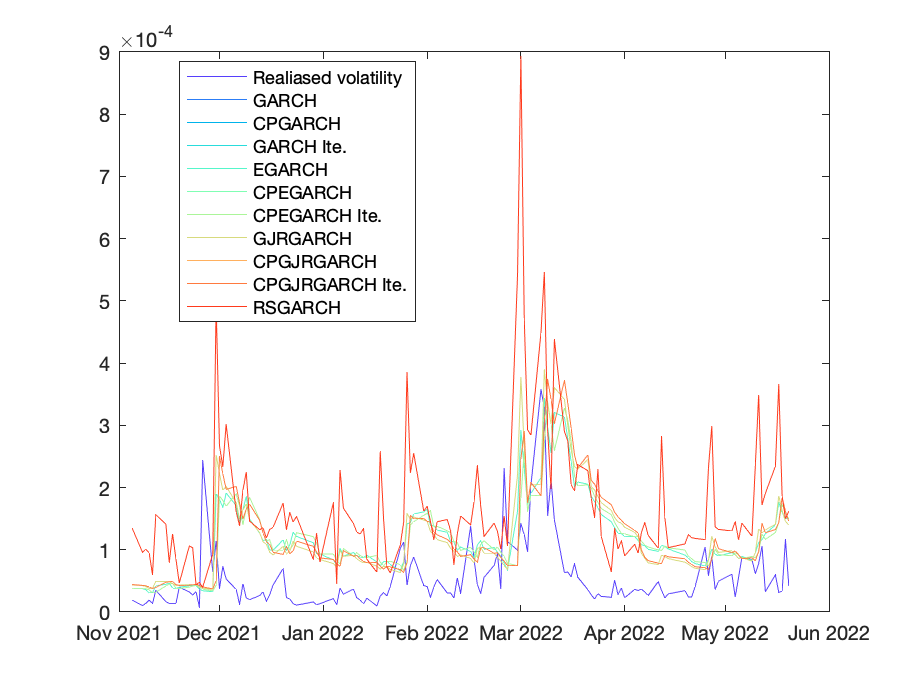

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              7.9712e-05     9.749e-05
    CPGARCH            7.9856e-05    9.9868e-05
    GARCH Ite.         7.9856e-05    9.9868e-05
    EGARCH             7.6158e-05    9.0614e-05
    CPEGARCH           7.7381e-05    9.3208e-05
    CPEGARCH Ite.      7.7381e-05    9.3208e-05
    GJRGARCH           7.9712e-05     9.749e-05
    CPGJRGARCH         7.9856e-05    9.9869e-05
    CPGJRGARCH Ite.    7.9856e-05    9.9869e-05
    RSGARCH            0.00012352    0.00015517


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);
[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);
[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound      R2   
                       _________    ___________    _______

    GARCH                0.2291       0.46315      0.20467
    CPGARCH             0.15393       0.40292      0.12826
    GARCH Ite.          0.15393       0.40292      0.12826
    EGARCH              0.25785       0.53781      0.19199
    CPEGARCH            0.16451       0.45999      0.11613
    CPEGARCH Ite.       0.16451       0.45999      0.11613
    GJRGARCH             0.2291       0.46315      0.20467
    CPGJRGARCH          0.15393       0.40292      0.12826
    CPGJRGARCH Ite.     0.15393       0.40292      0.12826
    RSGARCH             0.17109       0.31689      0.24783


## Figure of volatility persistence

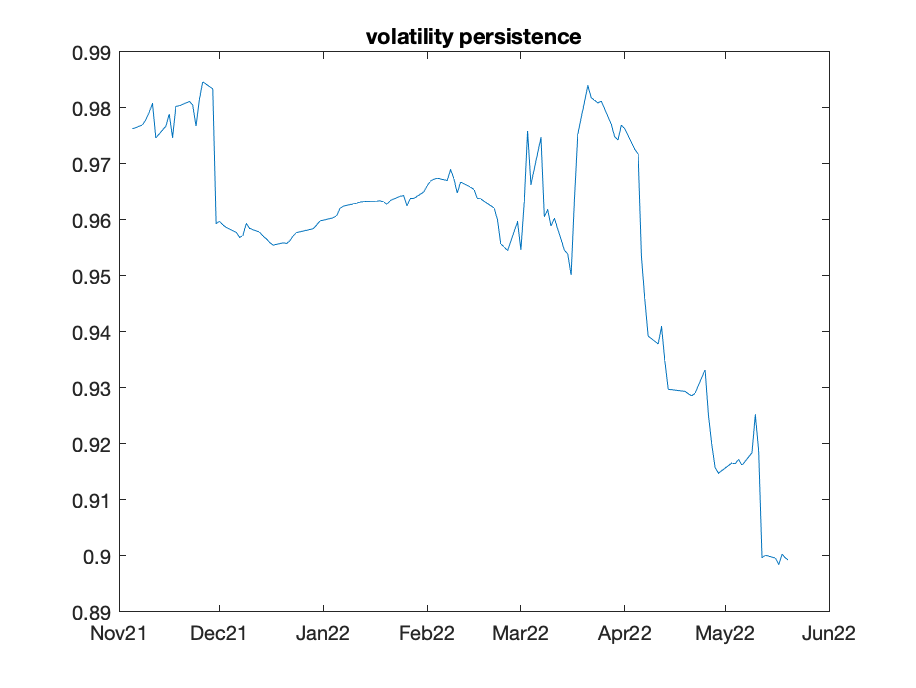

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_robust_',Index,'_20220522'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");

## NIKKIE225

Timeline=nikkie.Date;
Time_outsample=nikkie_rv_table.date;
logret=[0;price2ret(nikkie.Price)];
rv=nikkie_rv_table.rv;
Index='nikkie';

Set empty matrices

index=(Timeline>=Time_outsample(1) & Timeline<=Time_outsample(end));
if sum(index)~=numel(Time_outsample)
    warning("Dates of daily prices and realised volatilities do not match.")
end

Ret_outsample=logret(index);
OutsampleStart=find(Timeline==Time_outsample(1));
n=numel(Time_outsample);

v_residuals=Ret_outsample.^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vol_persis=zeros(n,1);

Rolling windows forecast

for t=1:n
    ret=logret(OutsampleStart+t-1-500:OutsampleStart+t-1-1,:);

    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(t)=forecast(EstMdl,1,ret);
    vol_persis(t)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    % CPGARCH
    [LB,J,~]=Fisher_div_sqr(v_GARCH,1);
    K = OptimalClusterNumber(v_GARCH,LB);
    if K==numel(v_GARCH)
        K=K-1;
    end
    [v_CPGARCH,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    vf_CPGARCH(t)=v_CPGARCH(end);

    % CPGARCH iteration
    v_CPGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGARCH);
    vf_CPGARCHiteration(t)=v_CPGARCHiteration(end);

    % EGARCH
    Mdl=egarch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(t)= forecast(EstMdl,1,ret);
    [LB,J,~]=Fisher_div_sqr(v_EGARCH,1);
    K = OptimalClusterNumber(v_EGARCH,LB);
    if K==numel(v_EGARCH)
        K=K-1;
    end
    [v_CPEGARCH,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    vf_CPEGARCH(t)=v_CPEGARCH(end);
    v_CPEGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPEGARCH);
    vf_CPEGARCHiteration(t)=v_CPEGARCHiteration(end);

    % GJR-GARCH
    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,'Display','off');
    vf_GJRGARCH(t)= forecast(EstMdl,1,ret);
    v_GJRGARCH = infer(EstMdl,ret);
    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,1);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    if K==numel(v_GJRGARCH)
        K=K-1;
    end
    [v_CPGJRGARCH,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    vf_CPGJRGARCH(t)=v_CPGJRGARCH(end);
    v_CPGJRGARCHiteration = Vol_ClusterPartitionIteration(Nodes,ret,v_CPGJRGARCH);
    vf_CPGJRGARCHiteration(t)=v_CPGJRGARCHiteration(end);

    % RSGARCH
    addpath("m_Files_swgarch")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_RSGARCH(t)=datafcst.vH;
    rmpath("m_Files_swgarch")
end

## Results: 9 graphs with "log returns", "residual squares", "GARCH conditional variance", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "GJRGARCH forecast" and "RSGARCH forecast"

figure;
subplot(5,2,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,2,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,2,3);
v_GARCH=estimateGARCH(Ret_outsample,garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN));
line(Time_outsample,v_GARCH);
ylabel('GARCH Con.Var.');dateaxis("x",12);
subplot(5,2,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH forecast');dateaxis("x",12);
subplot(5,2,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH forecast');dateaxis("x",12);
subplot(5,2,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite. ');dateaxis("x",12);
subplot(5,2,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,2,8);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,2,9);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: 13 graphs with "log returns", "residual squares", "realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

figure;
subplot(5,3,1);
line(Time_outsample,Ret_outsample);
ylabel('log returns');dateaxis("x",12);
subplot(5,3,2);
line(Time_outsample,v_residuals);
ylabel('residual square');dateaxis("x",12);
subplot(5,3,3);
line(Time_outsample,rv);
ylabel('realised volatility')
subplot(5,3,4);
line(Time_outsample,vf_GARCH);
ylabel('GARCH');dateaxis("x",12);
subplot(5,3,5);
line(Time_outsample,vf_CPGARCH);
ylabel('CPGARCH');dateaxis("x",12);
subplot(5,3,6);
line(Time_outsample,vf_CPGARCHiteration);
ylabel('CPGARCH Ite.');dateaxis("x",12);
subplot(5,3,7);
line(Time_outsample,vf_EGARCH);
ylabel('EGARCH');dateaxis("x",12);
subplot(5,3,8);
line(Time_outsample,vf_CPEGARCH);
ylabel('CPEGARCH');dateaxis("x",12);
subplot(5,3,9);
line(Time_outsample,vf_CPEGARCHiteration);
ylabel('CPEGARCH Ite.');dateaxis("x",12);
subplot(5,3,10);
line(Time_outsample,vf_GJRGARCH);
ylabel('GJRGARCH');dateaxis("x",12);
subplot(5,3,11);
line(Time_outsample,vf_CPGJRGARCH);
ylabel('CPGJRGARCH');dateaxis("x",12);
subplot(5,3,12);
line(Time_outsample,vf_CPGJRGARCHiteration);
ylabel('CPGJRGARCH Ite.');dateaxis("x",12);
subplot(5,3,13);
line(Time_outsample,vf_RSGARCH);
ylabel('RSGARCH');dateaxis("x",12);
set(gcf,'position',[500,500,500,650])

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast" and "CPGARCH iteration forecast"

figure;
col=rainbow(4);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:))
plot(Time_outsample,vf_CPGARCH, "Color",col(3,:))
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:))
legend("relisead volatility","GARCH","CPGARCH","GARCH iteration");

## Results: Figure of "Realised volatility", "GARCH forecast", "CPGARCH forecast", "CPGARCH iteration forecast", "EGARCH forecast", "CPEGARCH forecast", "CPEGARCH iteration forecast","GJRGARCH forecast", "CPGJRGARCH forecast", "CPGJRGARCH iteration forecast" and "RSGARCH forecast"

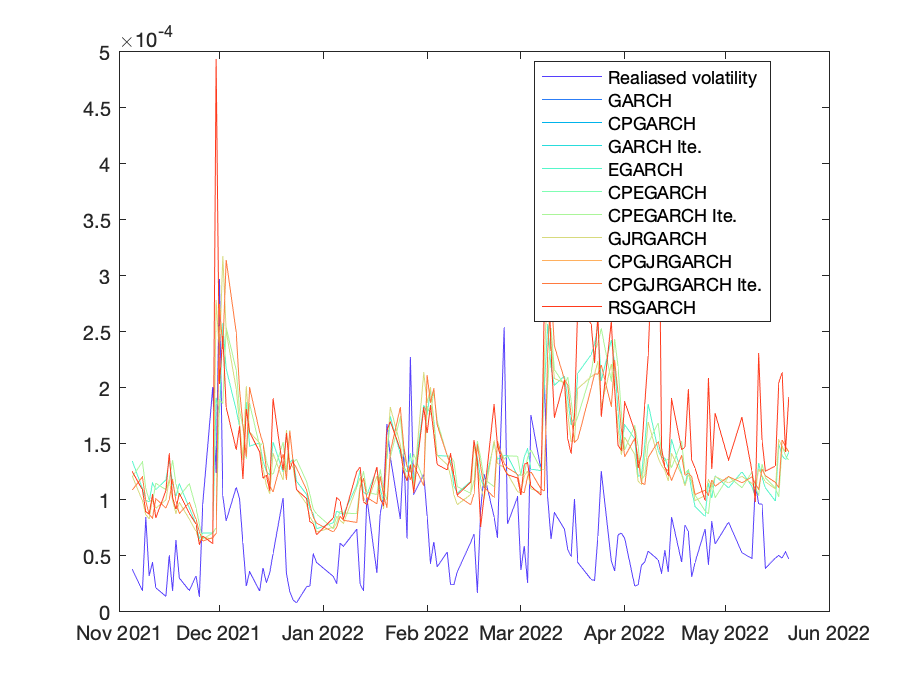

figure;
col=rainbow(11);
plot(Time_outsample,rv, "Color",col(1,:));hold on
plot(Time_outsample,vf_GARCH, "Color",col(2,:));
plot(Time_outsample,vf_CPGARCH,"Color",col(3,:));
plot(Time_outsample,vf_CPGARCHiteration, "Color",col(4,:));
plot(Time_outsample,vf_EGARCH, "Color",col(5,:));
plot(Time_outsample,vf_CPEGARCH, "Color",col(6,:));
plot(Time_outsample,vf_CPEGARCHiteration, "Color",col(7,:));
plot(Time_outsample,vf_GJRGARCH, "Color",col(8,:));
plot(Time_outsample,vf_CPGJRGARCH,"Color",col(9,:));
plot(Time_outsample,vf_CPGJRGARCHiteration, "Color",col(10,:));
plot(Time_outsample,vf_RSGARCH, "Color",col(11,:));
legend("Realiased volatility","GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH","Location","best");

%legend("boxoff")

MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              7.8555e-05    9.0488e-05
    CPGARCH            7.9823e-05    9.2545e-05
    GARCH Ite.         7.9823e-05    9.2545e-05
    EGARCH             8.1561e-05     9.293e-05
    CPEGARCH              8.3e-05    9.4499e-05
    CPEGARCH Ite.         8.3e-05    9.4499e-05
    GJRGARCH           7.8557e-05     9.049e-05
    CPGJRGARCH         7.9823e-05    9.2544e-05
    CPGJRGARCH Ite.    7.9823e-05    9.2544e-05
    RSGARCH            9.2268e-05    0.00011099


## Test of actual forecast: 

## actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);
[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);
[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH'})

ans = 10×3 table
                       low_bound    upper_bound       R2    
                       _________    ___________    _________

    GARCH               0.082883      0.43114       0.062473
    CPGARCH            -0.029259      0.32987       0.020981
    GARCH Ite.         -0.029259      0.32987       0.020981
    EGARCH             -0.019246      0.38797       0.024464
    CPEGARCH            -0.14113      0.27437      0.0031355
    CPEGARCH Ite.       -0.14113      0.27437      0.0031355
    GJRGARCH            0.082876       0.4311       0.062473
    CPGJRGARCH         -0.029254      0.32988       0.020983
    CPGJRGARCH Ite.    -0.029254      0.32988       0.020983
    RSGARCH            -0.024696      0

## Figure of volatility persistence

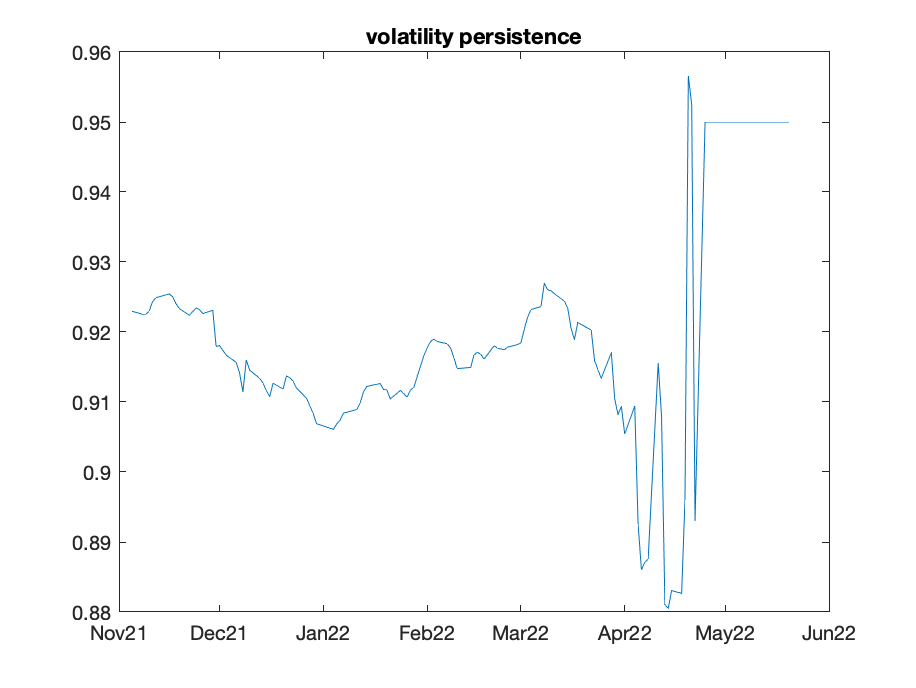

figure;
plot(Time_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_robust_',Index,'_20220522'),"rv","vol_persis","Time_outsample","vf_GARCH", ...
    "vf_EGARCH","vf_GJRGARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_CPEGARCH","vf_CPEGARCHiteration","vf_CPGJRGARCH", ...
    "vf_CPGJRGARCHiteration","Ret_outsample");
